# RICERCA SINGOLARITÀ

clear all
close all

### Definisco le variabili simboliche e carico RRR_data.mat

load RRR_data.mat
syms t
syms q1(t) q2(t) q3(t)
syms Q1 Q2 Q3 Q1p Q2p Q3p
Q(1)=q1;
Q(2)=q2;
Q(3)=q3;
L=sym("l",[1 4]);

### Calcolo Jacobiano

J=RRR_jacobian(Q,L);
Jp=diff(J,t)

Jp=subs(Jp,diff(q2),Q2p);
Jp=subs(Jp,diff(q1),Q1p);
Jp=subs(Jp,diff(q3),Q3p);
Jp=subs(Jp,q1,Q1);
Jp=subs(Jp,q2,Q2);
Jp=subs(Jp,q3,Q3)

$$Jp = \begin{array}{l} \left(\begin{array}{ccc} -\mathrm{Q1p}\,l_{1}\,\cos\left(Q_{1}\right) & \sigma_{1}-\sigma_{2}-\frac{\mathrm{Q2p}\,l_{4}\,\cos\left(Q_{2}\right)\,\sin\left(Q_{3}\right)}{2}-\frac{\mathrm{Q3p}\,l_{4}\,\cos\left(Q_{3}\right)\,\sin\left(Q_{2}\right)}{2}-\sigma_{7} & -\frac{l_{4}\,\left(\mathrm{Q3p}\,\cos\left(Q_{3}\right)-\mathrm{Q3p}\,\sin\left(Q_{3}\right)+\sigma_{6}+\sigma_{5}+\sigma_{4}-\sigma_{3}\right)}{2}\\ 0 & \mathrm{Q3p}\,l_{4}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}-\frac{\pi }{4}\right)-\mathrm{Q2p}\,\sin\left(Q_{2}\right)\,\left(\frac{\sqrt{2}\,l_{3}}{2}+l_{4}\,\sin\left(Q_{3}-\frac{\pi }{4}\right)\right) & \mathrm{Q2p}\,l_{4}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}+\frac{\pi }{4}\right)-\mathrm{Q3p}\,l_{4}\,\sin\left(Q_{2}\right)\,\sin\left(Q_{3}+\frac{\pi }{4}\right)\\ \mathrm{Q1p}\,l_{1}\,\sin\left(Q_{1}\right) & \sigma_{7}+\sigma_{2}-\sigma_{1} & \frac{l_{4}\,\left(\mathrm{Q3p}\,\sin\left(Q_{3}\right)-\mathrm{Q3p}\,\cos\left(Q_{3}\right)+\sigma_{6}+\sigma_{5}+\sigma_{4}-\sigma_{3}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{Q3p}\,l_{4}\,\sin\left(Q_{2}\right)\,\sin\left(Q_{3}\right)}{2}\\ \sigma_{2}=\frac{\mathrm{Q2p}\,l_{4}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}\right)}{2}\\ \sigma_{3}=\mathrm{Q2p}\,\sin\left(Q_{2}\right)\,\sin\left(Q_{3}\right)\\ \sigma_{4}=\mathrm{Q3p}\,\cos\left(Q_{2}\right)\,\sin\left(Q_{3}\right)\\ \sigma_{5}=\mathrm{Q2p}\,\cos\left(Q_{3}\right)\,\sin\left(Q_{2}\right)\\ \sigma_{6}=\mathrm{Q3p}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}\right)\\ \sigma_{7}=\frac{\mathrm{Q2p}\,l_{3}\,\cos\left(Q_{2}\right)}{2} \end{array}$$

Jp=matlabFunction(Jp)

Jp = function_handle with value:
    @(Q1,Q2,Q3,Q1p,Q2p,Q3p,l1,l3,l4)reshape([-Q1p.*l1.*cos(Q1),0.0,Q1p.*l1.*sin(Q1),Q2p.*l3.*cos(Q2).*(-1.0./2.0)-(Q2p.*l4.*cos(Q2).*cos(Q3))./2.0-(Q2p.*l4.*cos(Q2).*sin(Q3))./2.0-(Q3p.*l4.*cos(Q3).*sin(Q2))./2.0+(Q3p.*l4.*sin(Q2).*sin(Q3))./2.0,-Q2p.*sin(Q2).*((sqrt(2.0).*l3)./2.0+l4.*sin(Q3-pi./4.0))+Q3p.*l4.*cos(Q2).*cos(Q3-pi./4.0),(Q2p.*l3.*cos(Q2))./2.0+(Q2p.*l4.*cos(Q2).*cos(Q3))./2.0-(Q3p.*l4.*sin(Q2).*sin(Q3))./2.0,l4.*(Q3p.*cos(Q3)-Q3p.*sin(Q3)+Q3p.*cos(Q2).*cos(Q3)+Q2p.*cos(Q3).*sin(Q2)+Q3p.*cos(Q2).*sin(Q3)-Q2p.*sin(Q2).*sin(Q3)).*(-1.0./2.0),Q2p.*l4.*cos(Q2).*cos(Q3+pi./4.0)-Q3p.*l4.*sin(Q2).*sin(Q3+pi./4.0),(l4.*(-Q3p.*cos(Q3)+Q3p.*sin(Q3)+Q3p.*cos(Q2).*cos(Q3)+Q2p.*cos(Q3).*sin(Q2)+Q3p.*cos(Q2).*sin(Q3)-Q2p.*sin(Q2).*sin(Q3)))./2.0],[3,3])


detJ=det(J);
assume(Q,'positive')
detj=simplify(detJ)

latex(detJ)

ans = '\frac{l_{1}\,l_{3}\,l_{4}\,\cos\left(\frac{\pi }{4}+q_{3}\left(t\right)\right)\,\sin\left(q_{1}\left(t\right)\right)\,{\sin\left(q_{2}\left(t\right)\right)}^2}{2}+\frac{l_{1}\,{l_{4}}^2\,\cos\left(q_{1}\left(t\right)\right)\,\cos\left(q_{2}\left(t\right)\right)\,\cos\left(q_{3}\left(t\right)\right)\,\sin\left(\frac{\pi }{4}-q_{3}\left(t\right)\right)}{2}+\frac{l_{1}\,{l_{4}}^2\,\cos\left(q_{1}\left(t\right)\right)\,\cos\left(q_{3}\left(t\right)\right)\,\cos\left(\frac{\pi }{4}+q_{3}\left(t\right)\right)\,{\sin\left(q_{2}\left(t\right)\right)}^2}{2}+\frac{l_{1}\,{l_{4}}^2\,\cos\left(q_{1}\left(t\right)\right)\,\cos\left(q_{2}\left(t\right)\right)\,\sin\left(q_{3}\left(t\right)\right)\,\sin\left(\frac{\pi }{4}-q_{3}\left(t\right)\right)}{2}-\frac{l_{1}\,{l_{4}}^2\,\cos\left(q_{2}\left(t\right)\right)\,\cos\left(q_{3}\left(t\right)\right)\,\sin\left(q_{1}\left(t\right)\right)\,\sin\left(\frac{\pi }{4}-q_{3}\left(t\right)\right)}{2}+\frac{l_{1}\,{l_{4}}^2\,\cos\left(q_{1}\left(t\rig

detJ=matlabFunction(detJ);

J=matlabFunction(J)

J = function_handle with value:
    @(l1,l3,l4,t)reshape([-l1.*sin(q1(t)),0.0,-l1.*cos(q1(t)),l3.*sin(q2(t)).*(-1.0./2.0)-(l4.*cos(q3(t)).*sin(q2(t)))./2.0-(l4.*sin(q2(t)).*sin(q3(t)))./2.0,cos(q2(t)).*((sqrt(2.0).*l3)./2.0-l4.*sin(pi./4.0-q3(t))),(l3.*sin(q2(t)))./2.0+(l4.*cos(q3(t)).*sin(q2(t)))./2.0,l4.*(cos(q3(t))+sin(q3(t))+cos(q2(t)).*sin(q3(t))-cos(q2(t)).*cos(q3(t))).*(-1.0./2.0),l4.*cos(pi./4.0+q3(t)).*sin(q2(t)),l4.*(cos(q3(t))+sin(q3(t))-cos(q2(t)).*sin(q3(t))+cos(q2(t)).*cos(q3(t))).*(-1.0./2.0)],[3,3])


### Calcolo Jacobiano (vedere file .mlx per commenti)

clear all
Q=sym("q",[1 3])

$$Q = \left(\begin{array}{ccc} q_{1} & q_{2} & q_{3} \end{array}\right)$$

L=sym("l",[1 4])

$$L = \left(\begin{array}{cccc} l_{1} & l_{2} & l_{3} & l_{4} \end{array}\right)$$

load RRR_data.mat
[M01,M12,M23,M34,M04] = RRR_positionMat(Q,L);
S=M04*[0 0 0 1]'

$$S = \begin{array}{l} \left(\begin{array}{c} l_{2}+\frac{l_{3}}{2}-l_{4}\,\left(\sigma_{2}-\sigma_{1}\right)+l_{1}\,\cos\left(q_{1}\right)+\frac{l_{3}\,\cos\left(q_{2}\right)}{2}\\ \frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}+l_{4}\,\cos\left(q_{3}-\frac{\pi }{4}\right)\,\sin\left(q_{2}\right)\\ \frac{l_{3}}{2}-l_{4}\,\left(\sigma_{2}+\sigma_{1}\right)-\frac{l_{3}\,\cos\left(q_{2}\right)}{2}-l_{1}\,\sin\left(q_{1}\right)\\ 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}-\frac{\pi }{4}\right)}{2}\\ \sigma_{2}=\frac{\sqrt{2}\,\sin\left(q_{3}-\frac{\pi }{4}\right)}{2} \end{array}$$

S=S(1:3)

$$S = \begin{array}{l} \left(\begin{array}{c} l_{2}+\frac{l_{3}}{2}-l_{4}\,\left(\sigma_{2}-\sigma_{1}\right)+l_{1}\,\cos\left(q_{1}\right)+\frac{l_{3}\,\cos\left(q_{2}\right)}{2}\\ \frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}+l_{4}\,\cos\left(q_{3}-\frac{\pi }{4}\right)\,\sin\left(q_{2}\right)\\ \frac{l_{3}}{2}-l_{4}\,\left(\sigma_{2}+\sigma_{1}\right)-\frac{l_{3}\,\cos\left(q_{2}\right)}{2}-l_{1}\,\sin\left(q_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}-\frac{\pi }{4}\right)}{2}\\ \sigma_{2}=\frac{\sqrt{2}\,\sin\left(q_{3}-\frac{\pi }{4}\right)}{2} \end{array}$$

J=jacobian(S,Q)

$$J = \begin{array}{l} \left(\begin{array}{ccc} -l_{1}\,\sin\left(q_{1}\right) & -\sigma_{1}-\sigma_{2} & -l_{4}\,\left(\frac{\sqrt{2}\,\sigma_{4}}{2}+\sigma_{3}\right)\\ 0 & l_{4}\,\cos\left(q_{2}\right)\,\sigma_{4}+\frac{\sqrt{2}\,l_{3}\,\cos\left(q_{2}\right)}{2} & -l_{4}\,\sin\left(q_{2}\right)\,\sigma_{5}\\ -l_{1}\,\cos\left(q_{1}\right) & \sigma_{1}+\sigma_{2} & -l_{4}\,\left(\frac{\sqrt{2}\,\sigma_{4}}{2}-\sigma_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{l_{3}\,\sin\left(q_{2}\right)}{2}\\ \sigma_{2}=\frac{\sqrt{2}\,l_{4}\,\sigma_{4}\,\sin\left(q_{2}\right)}{2}\\ \sigma_{3}=\frac{\sqrt{2}\,\cos\left(q_{2}\right)\,\sigma_{5}}{2}\\ \sigma_{4}=\cos\left(q_{3}-\frac{\pi }{4}\right)\\ \sigma_{5}=\sin\left(q_{3}-\frac{\pi }{4}\right) \end{array}$$

latex(J)

ans = '\left(\begin{array}{ccc} -l_{1}\,\sin\left(q_{1}\right) & -\frac{l_{3}\,\sin\left(q_{2}\right)}{2}-\frac{\sqrt{2}\,l_{4}\,\cos\left(q_{3}-\frac{\pi }{4}\right)\,\sin\left(q_{2}\right)}{2} & -l_{4}\,\left(\frac{\sqrt{2}\,\cos\left(q_{3}-\frac{\pi }{4}\right)}{2}+\frac{\sqrt{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}-\frac{\pi }{4}\right)}{2}\right)\\ 0 & l_{4}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}-\frac{\pi }{4}\right)+\frac{\sqrt{2}\,l_{3}\,\cos\left(q_{2}\right)}{2} & -l_{4}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}-\frac{\pi }{4}\right)\\ -l_{1}\,\cos\left(q_{1}\right) & \frac{l_{3}\,\sin\left(q_{2}\right)}{2}+\frac{\sqrt{2}\,l_{4}\,\cos\left(q_{3}-\frac{\pi }{4}\right)\,\sin\left(q_{2}\right)}{2} & -l_{4}\,\left(\frac{\sqrt{2}\,\cos\left(q_{3}-\frac{\pi }{4}\right)}{2}-\frac{\sqrt{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}-\frac{\pi }{4}\right)}{2}\right) \end{array}\right)'

detJ=det(J);

J=matlabFunction(J)

J = function_handle with value:
    @(l1,l3,l4,q1,q2,q3)reshape([-l1.*sin(q1),0.0,-l1.*cos(q1),l3.*sin(q2).*(-1.0./2.0)-(sqrt(2.0).*l4.*cos(q3-pi./4.0).*sin(q2))./2.0,l4.*cos(q2).*cos(q3-pi./4.0)+(sqrt(2.0).*l3.*cos(q2))./2.0,(l3.*sin(q2))./2.0+(sqrt(2.0).*l4.*cos(q3-pi./4.0).*sin(q2))./2.0,-l4.*((sqrt(2.0).*cos(q3-pi./4.0))./2.0+(sqrt(2.0).*cos(q2).*sin(q3-pi./4.0))./2.0),-l4.*sin(q2).*sin(q3-pi./4.0),-l4.*((sqrt(2.0).*cos(q3-pi./4.0))./2.0-(sqrt(2.0).*cos(q2).*sin(q3-pi./4.0))./2.0)],[3,3])


## Calcolo Jacobiano punto (vedere file .mlx per commenti)

clear all
load RRR_data.mat
syms t
syms q1(t) q2(t) q3(t)
syms Q1 Q2 Q3 Q1p Q2p Q3p
Q(1)=q1;
Q(2)=q2;
Q(3)=q3;
L=sym("l",[1 4]);
J=RRR_jacobian(Q,L);
Jp=diff(J,t)


Jp=subs(Jp,diff(q2),Q2p);
Jp=subs(Jp,diff(q1),Q1p);
Jp=subs(Jp,diff(q3),Q3p);
Jp=subs(Jp,q1,Q1);
Jp=subs(Jp,q2,Q2);
Jp=subs(Jp,q3,Q3)

$$Jp = \begin{array}{l} \left(\begin{array}{ccc} -\mathrm{Q1p}\,l_{1}\,\cos\left(Q_{1}\right) & \sigma_{1}-\sigma_{2}-\frac{\mathrm{Q2p}\,l_{4}\,\cos\left(Q_{2}\right)\,\sin\left(Q_{3}\right)}{2}-\frac{\mathrm{Q3p}\,l_{4}\,\cos\left(Q_{3}\right)\,\sin\left(Q_{2}\right)}{2}-\sigma_{7} & -\frac{l_{4}\,\left(\mathrm{Q3p}\,\cos\left(Q_{3}\right)-\mathrm{Q3p}\,\sin\left(Q_{3}\right)+\sigma_{6}+\sigma_{5}+\sigma_{4}-\sigma_{3}\right)}{2}\\ 0 & \mathrm{Q3p}\,l_{4}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}-\frac{\pi }{4}\right)-\mathrm{Q2p}\,\sin\left(Q_{2}\right)\,\left(\frac{\sqrt{2}\,l_{3}}{2}+l_{4}\,\sin\left(Q_{3}-\frac{\pi }{4}\right)\right) & \mathrm{Q2p}\,l_{4}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}+\frac{\pi }{4}\right)-\mathrm{Q3p}\,l_{4}\,\sin\left(Q_{2}\right)\,\sin\left(Q_{3}+\frac{\pi }{4}\right)\\ \mathrm{Q1p}\,l_{1}\,\sin\left(Q_{1}\right) & \sigma_{7}+\sigma_{2}-\sigma_{1} & \frac{l_{4}\,\left(\mathrm{Q3p}\,\sin\left(Q_{3}\right)-\mathrm{Q3p}\,\cos\left(Q_{3}\right)+\sigma_{6}+\sigma_{5}+\sigma_{4}-\sigma_{3}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{Q3p}\,l_{4}\,\sin\left(Q_{2}\right)\,\sin\left(Q_{3}\right)}{2}\\ \sigma_{2}=\frac{\mathrm{Q2p}\,l_{4}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}\right)}{2}\\ \sigma_{3}=\mathrm{Q2p}\,\sin\left(Q_{2}\right)\,\sin\left(Q_{3}\right)\\ \sigma_{4}=\mathrm{Q3p}\,\cos\left(Q_{2}\right)\,\sin\left(Q_{3}\right)\\ \sigma_{5}=\mathrm{Q2p}\,\cos\left(Q_{3}\right)\,\sin\left(Q_{2}\right)\\ \sigma_{6}=\mathrm{Q3p}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}\right)\\ \sigma_{7}=\frac{\mathrm{Q2p}\,l_{3}\,\cos\left(Q_{2}\right)}{2} \end{array}$$

latex(Jp)

ans = '\left(\begin{array}{ccc} -\mathrm{Q1p}\,l_{1}\,\cos\left(Q_{1}\right) & \frac{\mathrm{Q3p}\,l_{4}\,\sin\left(Q_{2}\right)\,\sin\left(Q_{3}\right)}{2}-\frac{\mathrm{Q2p}\,l_{4}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}\right)}{2}-\frac{\mathrm{Q2p}\,l_{4}\,\cos\left(Q_{2}\right)\,\sin\left(Q_{3}\right)}{2}-\frac{\mathrm{Q3p}\,l_{4}\,\cos\left(Q_{3}\right)\,\sin\left(Q_{2}\right)}{2}-\frac{\mathrm{Q2p}\,l_{3}\,\cos\left(Q_{2}\right)}{2} & -\frac{l_{4}\,\left(\mathrm{Q3p}\,\cos\left(Q_{3}\right)-\mathrm{Q3p}\,\sin\left(Q_{3}\right)+\mathrm{Q3p}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}\right)+\mathrm{Q2p}\,\cos\left(Q_{3}\right)\,\sin\left(Q_{2}\right)+\mathrm{Q3p}\,\cos\left(Q_{2}\right)\,\sin\left(Q_{3}\right)-\mathrm{Q2p}\,\sin\left(Q_{2}\right)\,\sin\left(Q_{3}\right)\right)}{2}\\ 0 & \mathrm{Q3p}\,l_{4}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}-\frac{\pi }{4}\right)-\mathrm{Q2p}\,\sin\left(Q_{2}\right)\,\left(\frac{\sqrt{2}\,l_{3}}{2}+l_{4}\,\sin\left(Q_{3}-\frac{\pi }{4}\right)\

Jp=matlabFunction(Jp)

Jp = function_handle with value:
    @(Q1,Q2,Q3,Q1p,Q2p,Q3p,l1,l3,l4)reshape([-Q1p.*l1.*cos(Q1),0.0,Q1p.*l1.*sin(Q1),Q2p.*l3.*cos(Q2).*(-1.0./2.0)-(Q2p.*l4.*cos(Q2).*cos(Q3))./2.0-(Q2p.*l4.*cos(Q2).*sin(Q3))./2.0-(Q3p.*l4.*cos(Q3).*sin(Q2))./2.0+(Q3p.*l4.*sin(Q2).*sin(Q3))./2.0,-Q2p.*sin(Q2).*((sqrt(2.0).*l3)./2.0+l4.*sin(Q3-pi./4.0))+Q3p.*l4.*cos(Q2).*cos(Q3-pi./4.0),(Q2p.*l3.*cos(Q2))./2.0+(Q2p.*l4.*cos(Q2).*cos(Q3))./2.0-(Q3p.*l4.*sin(Q2).*sin(Q3))./2.0,l4.*(Q3p.*cos(Q3)-Q3p.*sin(Q3)+Q3p.*cos(Q2).*cos(Q3)+Q2p.*cos(Q3).*sin(Q2)+Q3p.*cos(Q2).*sin(Q3)-Q2p.*sin(Q2).*sin(Q3)).*(-1.0./2.0),Q2p.*l4.*cos(Q2).*cos(Q3+pi./4.0)-Q3p.*l4.*sin(Q2).*sin(Q3+pi./4.0),(l4.*(-Q3p.*cos(Q3)+Q3p.*sin(Q3)+Q3p.*cos(Q2).*cos(Q3)+Q2p.*cos(Q3).*sin(Q2)+Q3p.*cos(Q2).*sin(Q3)-Q2p.*sin(Q2).*sin(Q3)))./2.0],[3,3])


## Disegno determinante jacobiano

clear all
close all
load RRR_data.mat
L=link;
Q=sym("q",[1 3]);
detJ=detJacobian(Q,link)

$$detJ = \begin{array}{l} \frac{2\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sigma_{1}\,\left(\cos\left(q_{3}\right)+\sin\left(q_{3}\right)+\sigma_{5}-\sigma_{4}\right)}{25}-\frac{2\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sigma_{1}\,\left(\cos\left(q_{3}\right)+\sin\left(q_{3}\right)-\sigma_{5}+\sigma_{4}\right)}{25}+\frac{4\,\sigma_{6}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(\sigma_{3}+\sigma_{2}\right)}{25}+\frac{4\,\cos\left(q_{1}\right)\,\sigma_{6}\,\sin\left(q_{2}\right)\,\left(\sigma_{3}+\sigma_{2}+\frac{\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{5}\right)}{25}\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,\sin\left(q_{3}-\frac{\pi }{4}\right)}{5}+\frac{3\,\sqrt{2}}{10}\\ \sigma_{2}=\frac{\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)}{5}\\ \sigma_{3}=\frac{3\,\sin\left(q_{2}\right)}{10}\\ \sigma_{4}=\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{5}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\\ \sigma_{6}=\cos\left(q_{3}+\frac{\pi }{4}\right) \end{array}$$

latex(detJ)

ans = '\frac{2\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(\frac{2\,\sin\left(q_{3}-\frac{\pi }{4}\right)}{5}+\frac{3\,\sqrt{2}}{10}\right)\,\left(\cos\left(q_{3}\right)+\sin\left(q_{3}\right)+\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)}{25}-\frac{2\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(\frac{2\,\sin\left(q_{3}-\frac{\pi }{4}\right)}{5}+\frac{3\,\sqrt{2}}{10}\right)\,\left(\cos\left(q_{3}\right)+\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)}{25}+\frac{4\,\cos\left(q_{3}+\frac{\pi }{4}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(\frac{3\,\sin\left(q_{2}\right)}{10}+\frac{\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)}{5}\right)}{25}+\frac{4\,\cos\left(q_{1}\right)\,\cos\left(q_{3}+\frac{\pi }{4}\right)\,\sin\left(q_{2}\right)\,\left(\frac{3\,\sin\left(q_{2}\right)}{10}+\frac{\cos\left(q_{3}\right)\,\sin\left(

eqn=simplify(detJ)

$$eqn = \begin{array}{l} \frac{2\,\cos\left(q_{1}\right)\,\sigma_{4}\,{\sin\left(q_{2}\right)}^{2}\,\left(2\,\sqrt{2}\,\sin\left(q_{3}+\frac{\pi }{4}\right)+3\right)}{125}+\frac{2\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sigma_{3}\,\left(\cos\left(q_{3}\right)+\sin\left(q_{3}\right)-\sigma_{2}+\sigma_{1}\right)}{25}-\frac{2\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sigma_{3}\,\left(\cos\left(q_{3}\right)+\sin\left(q_{3}\right)+\sigma_{2}-\sigma_{1}\right)}{25}+\frac{2\,\sigma_{4}\,\sin\left(q_{1}\right)\,{\sin\left(q_{2}\right)}^{2}\,\left(2\,\cos\left(q_{3}\right)+3\right)}{125}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{2}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\\ \sigma_{3}=\frac{2\,\sigma_{4}}{5}-\frac{3\,\sqrt{2}}{10}\\ \sigma_{4}=\cos\left(q_{3}+\frac{\pi }{4}\right) \end{array}$$


ep= eqn; %e primo

ep==0;

ep=solve(ep,Q(3))

$$ep = 2\,\pi \,k-\log\left(z_{1}\right)\,\mathrm{i}$$


eqn=solve(eqn,Q(3))

$$eqn = 2\,\pi \,k-\log\left(z_{1}\right)\,\mathrm{i}$$

eqn=matlabFunction(eqn)

eqn = function_handle with value:
    @(k,z1)log(z1).*-1i+k.*pi.*2.0


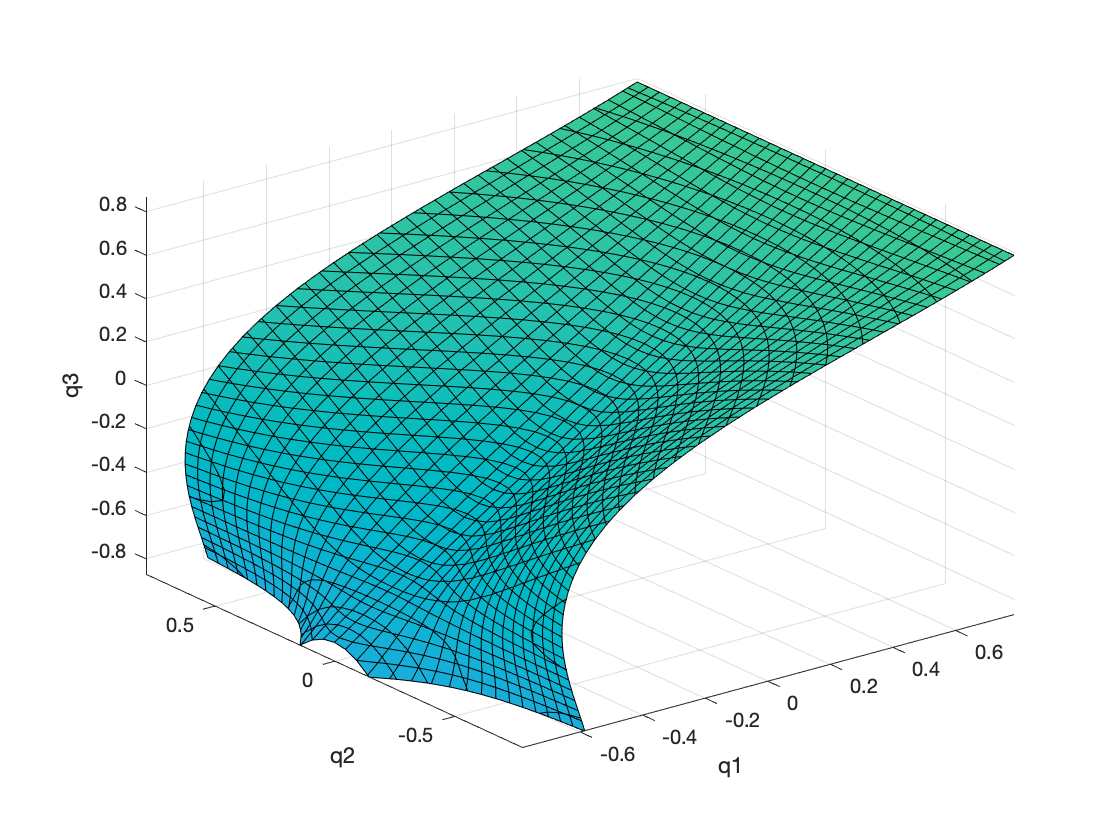

fimplicit3(detJ)
xlim([-Con(1,1) Con(1,1)])
ylim([-Con(1,2) Con(1,2)])
zlim([-Con(1,3) Con(1,3)])
xlabel("q1")
ylabel("q2")
zlabel("q3")

## Prova -> plot di alcune singolarità e dei punti

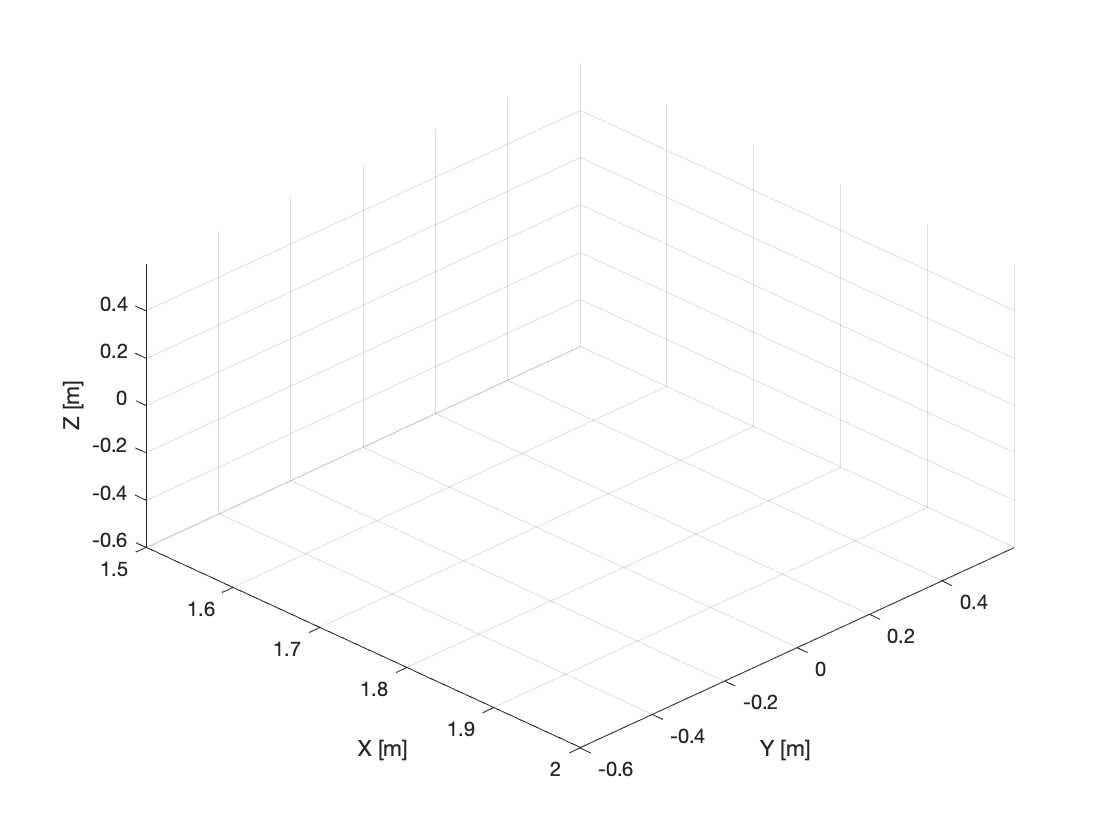

close all
a=100;
b=100;
i=0;
realSol=NaN(3,a*b*4);
for q1 = linspace(-Con(1,1),Con(1,1),a)
    for q2 = linspace(-Con(1,2),Con(1,2),b)
        q3=eqn(q1,q2);
        for q=q3'
            if (q>=-Con(1,3))&&(q<=Con(1,3))
                if isreal(q)
                    i=i+1;
                    realSol(:,i)=[q1;q2;q];
                end
            end
        end
        
    end
end
for i=1:a*b*4
    if(isnan(realSol(1,i)))
        length=i-1;
        break
    end
end
realSol=realSol(:,1:length);
plot3(realSol(1,:),realSol(2,:),realSol(3,:),'.')
xlim([1.5 2]) %Sta tra 1.5m e 2m
ylim([-0.6 0.6]) %Sta tra -0.6m e 0.6m
zlim([-0.6 0.6]) %Sta tra -0.6m e 0.6m
xlabel("X [m]")
ylabel("Y [m]")
zlabel("Z [m]")
view([45 45])
grid on

S=zeros(4,length);
for i=1:length
    S(:,i)=RRR_cinDir(realSol(:,i),link);
end

### Disegno le singolarità del robot (che noi non abbiamo)

for i=1:length
    figure
    plotRRR_3D(link, realSol(:,i))
    xlabel("X [m]")
    ylabel("Y [m]")
    zlabel("Z [m]")
    view([45 45])
    axis equal
end

### Salvo le singolarità (che noi non abbiamo)

%save Singolarità_Cartesiane S space X Xdiv Y Ydiv Z Zdiv